# Molico (2006) Replication

## Calibration

clear all
close all
clc

tic

mupper=700 %highest value if money holdings on the grid

mupper = 700

N=1000 %number of agents for simulating distribution

N = 1000

iterations=10 %maximum number of iterations for the value function iteration    

iterations = 10

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.25

x = 0.2500

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=100 %Money supply

M = 100

r=1/beta-1 %real interest rate

r = 0.0101

mu_all=[0, 0.01, 0.05, 0.2] %Money Growth

mu_all =          0    0.0100    0.0500    0.2000


mu_labels={ 'Price Stability', 'Mild inflation'...
    , 'Medium inflation', 'high inflation'}

mu_labels = 1×4 cell array
    {'Price Stability'}    {'Mild inflation'}    {'Medium inflation'}    {'high inflation'}


n_calibration=size(mu_all)

n_calibration =      1     4


n_calibration=n_calibration(1,2)

n_calibration = 4

smoothing_parameter=0.3

smoothing_parameter = 0.3000

correct_dist=1

correct_dist = 1

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
grids_1=3

grids_1 = 3

grids_2=14

grids_2 = 14

grids_3=3

grids_3 = 3

grids=grids_1+grids_2+grids_3

grids = 20


m_0=linspace(0,80,grids_1)

m_0 =      0    40    80


m_1=linspace(90,200, grids_2)

m_1 =    90.0000   98.4615  106.9231  115.3846  123.8462  132.3077  140.7692  149.2308  157.6923  166.1538  174.6154  183.0769  191.5385  200.0000


 m_2=linspace(220,mupper,grids_3);
 m=[m_0,m_1,m_2]

m =          0   40.0000   80.0000   90.0000   98.4615  106.9231  115.3846  123.8462  132.3077  140.7692  149.2308  157.6923  166.1538  174.6154  183.0769  191.5385  200.0000  220.0000  460.0000  700.0000


% grids=20
% m=linspace(0,mupper, grids)


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function
test_utility=0; % displays the utility and cost function

display_plot_all=1;
display_plot_V=1;
display_plot_q=1;
display_plot_d=1;
display_plot_meeting=1;
display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=1;
display_plot_cdf=0;
display_plot_money_savings=0;
display_plot_M_Track_1=1;
display_plot_q_all=1;
display_plot_d_all=1;






## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids);
m_savings_2=zeros(1,grids);
m_savings_3=zeros(1,grids);

V_all=zeros(grids,n_calibration);
Distribution_all=zeros(N,n_calibration);
q_all=zeros(grids, grids,n_calibration);
d_all=zeros(grids, grids,n_calibration);
price_all=zeros(grids, grids,n_calibration);
f=zeros(100,n_calibration);
xi=zeros(100,n_calibration);
M_track_1=zeros(iterations,n_calibration);

average_price=zeros(1,n_calibration);
std_distribution=zeros(1,n_calibration);
velocity=zeros(1,n_calibration);
average_real_balances=zeros(1,n_calibration);

## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M_0=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Test interpolation: spline, extrapolate


if test_interpolation==1
    n_interp=1000
V_interp=ones(n_interp);
m_interp=linspace(1,mupper,n_interp);
for i=1:n_interp
V_interp=interp1(m,V0,m_interp,'spline',"extrap");
end

%Plot
hold on

plot(m,V0)
plot(m_interp,V_interp)
legend('grids', 'interpolation')

hold off

clear  m_interp n_interp V_interp
end


## Test utility and cost function


if test_utility==1
u=Utility(m)
c=cost_function(m)
s=u-c
figure(1)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
clear u c s
end

## Iteration

 for calibriation=1:n_calibration
mu=mu_all(1,calibriation);
[V_all(:,calibriation), q_all(:,:,calibriation),d_all(:,:,calibriation),Distribution_all(:,calibriation),...
    lamdba,cdf,M_track_1(:,calibriation), M_track_2,Meeting,i] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,M_0,r,alpha,x,mu,theta,mupper, stopping_parameter,correct_dist)

 if cdf(grids)==1
    disp('cdf adds up to one')
else 
    disp('cdf does not add up to one')
    cdf(grids)
 end



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692         0         0         0         0         0         0         0         0         0


Distribution_new =   106.9231  106.9231  106.9231  100.3873  113.4589  113.4589  100.3873  113.4589  100.3873  113.4589  100.3873  106.9231  106.9231  106.9231  106.9231  113.4589  100.3873  113.4589  100.3873  113.4589  100.3873  113.4589  100.3873  100.3873  113.4589  113.4589  100.3873  106.9231  106.9231  100.3873  113.4589  106.9231  106.9231  106.9231  100.3873  113.4589  106.9231  106.9231  106.9231  106.9231  100.3873  113.4589  113.4589  100.3873  100.3873  113.4589  106.9231  100.3873  113.4589  113.4589


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692         0         0         0         0         0         0         0         0


Distribution_new =   106.9231  100.4399  113.4062  106.6899  107.1562  120.4158   93.4304  120.4158   93.4304  106.7347  107.1114  113.4062  100.4399  106.9231  113.4062  106.9757  100.3873  113.4589   94.1629  119.6832   93.9679  119.8782  100.3873  100.3873  113.4589  120.4158   93.4304  106.9231  100.4399  106.8704  113.4589  100.4399  113.4062  100.2368  107.0735  113.4589  106.9231  106.9231  106.9231  100.4399  106.8704  113.4589  113.4589  100.3873  100.3873  106.5201  113.8619  106.9848  106.8613  120.4158


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692         0         0         0         0         0         0         0


Distribution_new =   106.9231  106.6830  107.1632  113.4274  100.4187  126.9344   86.9118  127.5084   86.3377  100.1034  113.7427  113.4062  100.4399  100.0834  120.2459  106.9757  100.3873  113.4589  100.5197  113.3264  100.3210  113.5252  100.3873   94.4181  119.4281  127.5084   86.3377  100.0834  107.2796  113.6131  106.7162  106.6830  107.1632  100.2368  107.0735  106.5643  113.8176  113.3548  100.4914  100.4399  106.8704  120.3754  106.5424  100.3873   93.9690  112.9384  121.0750   99.7716  106.8613  120.4158


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692         0         0         0         0         0         0


Distribution_new =   100.3171  113.2890  113.8642  106.7264   94.4218  132.9313   86.9118  134.4001   79.4460  106.5939  107.2522  106.7829  107.0633  100.0834  120.2459  106.9757  100.3873  107.1229  106.8557  106.9496  106.6978  113.5252  100.3873  100.5040  113.3421  135.0422   78.8040  107.1083  100.2547  113.6131  113.4042   99.9951  107.1632   93.7900  113.5204  112.9445  107.4375  113.3548   94.0434  106.8879  106.8704  127.4224   99.4954  100.3873   87.3630  119.5444  121.0750  106.2530  100.3800  120.4158


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692         0         0         0         0         0


Distribution_new =   106.7819  106.8241  113.8642  106.7264   94.4218  125.2187   94.6244  127.1304   86.7157  113.2421  100.6041  106.7829  107.0633  106.2021  114.1272  106.9757  106.5845  100.9257  106.8557  106.9496  106.6978  113.5252  100.3873  106.9758  106.8703  142.7249   71.1212  100.9414  106.4216  113.6131  107.0060  106.3932  107.1632  100.9647  106.3456  112.9445  100.6302  120.1620   94.0434  106.8879  106.8704  127.4224   99.4954   94.3220   93.4282  126.5269  114.0925  106.2530   93.8800  126.9157


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692         0         0         0         0


Distribution_new =   106.7819  113.1842  107.5041  106.7264  100.6366  119.0039   94.6244  127.1304   86.7157  106.4804  107.3657  113.3837  100.4625   99.9163  120.4130  106.9757  113.7381   93.7720  114.0174   99.7879  113.2963  106.9267  100.3873  106.9758  106.8703  150.5512   63.2950  100.9414  100.0681  119.9666  113.6127   99.7865  107.1632  100.9647  106.3456  106.1928  107.3819  120.1620   94.0434  100.3004  113.4579  127.4224   99.4954   94.3220   93.4282  133.4337  107.1857  106.2530   87.4839  133.3118


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692         0         0         0


Distribution_new =   106.7819  113.1842  113.9911  100.2393  100.6366  119.0039  101.0112  120.7436   86.7157  112.8545  100.9917  106.5498  107.2964   99.9163  120.4130  100.3709  120.3429   86.3956  121.3939  106.4445  106.6398  100.5425  106.7715  106.9758  100.2665  157.1550   69.5293   94.7071   93.4125  126.6222  120.6532   92.7460  107.1632  107.3278   99.9826  112.7542  100.8205  113.5491  100.6564  106.6577  107.1006  127.4224   99.4954  101.0166   86.7336  133.4337  114.5884   98.8503   94.4641  126.3317


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692         0         0


Distribution_new =   100.3515  119.6147  107.4570  106.7735   94.1292  125.5113  107.5085  114.2463   94.3237  105.2465  107.4919  100.0496  107.2964   93.1733  127.1560   93.8566  126.8572   86.3956  121.3939  106.4445  106.6398  100.5425  106.7715  106.9758  106.9978  150.4237   75.9793   88.2571   93.4125  126.6222  120.6532   99.3591  100.5500  113.7663   93.5440  112.7542   94.1030  120.2667  100.6564  106.6577  107.1006  127.4224   99.4954  101.0166   93.5112  126.6562  122.1735   91.2652  101.2688  119.5269


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692         0


Distribution_new =    93.5416  126.4246  107.4570  106.7735   87.3363  132.3042  107.5085  114.2463  101.2125   98.3577  100.9939  106.5476  100.6196   99.8501  127.1560   87.0581  133.6557   93.1440  114.6454  106.4445  113.1365   94.0458  113.2700  100.4773  100.3138  157.1077   69.7397   94.4967   93.4125  126.6222  113.7503  106.2621   93.7458  120.5706   86.3074  119.9907   87.1131  127.2566  100.6564   99.7489  114.0094  134.6193   92.2985  107.4820   87.0458  119.5498  129.2799   91.2652   94.6747  126.1210


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692


Distribution_new =   101.0588  118.9074  107.4570  106.7735   87.3363  132.3042  100.9237  120.8311  101.2125  105.1586   94.1929   99.9522  107.2150   92.5008  134.5053   80.2160  140.4978   93.1440  114.6454   99.8477  119.7332   87.1710  120.1448  107.0711   93.7200  148.3052   78.5422   94.4967   93.4125  126.6222  106.9442  113.0682   93.7458  120.5706   93.1460  113.1522   87.1131  134.5484   93.3646   99.7489  114.0094  127.4173   99.5005  107.4820   94.1239  112.4718  121.8954   98.6497   87.8058  132.9900


Value function has not converged


i = 10

V_all =     0.0000         0         0         0
  431.7010         0         0         0
  529.1905         0         0         0
  538.1957         0         0         0
  546.0211         0         0         0
  554.1264         0         0         0
  562.0372         0         0         0
  569.4557         0         0         0
  576.3637         0         0         0
  582.8192         0         0         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9225    0.8573    0.6735    0.6748    0.6817    0.6802    0.6711    0.6598    0.6487    0.6380    0.6277    0.6177    0.6081    0.5987    0.5896    0.5809    0.5718    0.5544    0.3567    0.0000
    0.9669    0.9366    0.8505    0.8537    0.8559    0.8533    0.8478    0.8420    0.8362    0.8306    0.8252    0.8199    0.8147    0.8097    0.8048    0.7998    0.7949    0.7859    0.6642    0.0000
    0.9677    0.9390    0.8629    0.8662    0.8676    0.8649    0.8601    0.8550    0.8501    0.8454    0.8408    0.8363    0.8319    0.8277    0.8236    0.8194    0.8153    0.8079    0.7048    0.0000
    0.9670    0.9379    0.8622    0.8656    0.8669    0.8642    0.8594    0.8545    0.8498    0.8452    0.8408    0.8365    0.8323    0.8283    0.8244    0.8204    0.8165  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6801    1.1636    2.2584    2.2843    2.2480    2.2355    2.2675    2.3165    2.3644    2.4087    2.4498    2.4880    2.5235    2.5564    2.5871    2.6153    2.6421    2.6969    2.8540         0
    1.6887    2.9674    6.2981    6.3471    6.2019    6.1751    6.2981    6.4731    6.6460    6.8103    6.9667    7.1157    7.2582    7.3942    7.5259    7.6464    7.7754    8.0294   10.2956         0
    1.7357    3.1004    6.9776    7.0290    6.8427    6.8126    6.9683    7.1877    7.4059    7.6149    7.8155    8.0081    8.1936    8.3719    8.5461    8.7051    8.8800    9.2217   12.4698         0
    1.6949    3.0341    6.9378    6.9917    6.7990    6.7677    6.9287    7.1568    7.3847    7.6040    7.8154    8.0194    8.2167    8.4072    8.5941    8.7652    8.9542  

Distribution_all =   101.0588         0         0         0
  118.9074         0         0         0
  107.4570         0         0         0
  106.7735         0         0         0
   87.3363         0         0         0
  132.3042         0         0         0
  100.9237         0         0         0
  120.8311         0         0         0
  101.2125         0         0         0
  105.1586         0         0         0


lamdba =          0         0    0.0720    0.1020    0.1200    0.2120    0.2040    0.1220    0.0730    0.0570    0.0310    0.0040    0.0030         0         0         0         0         0         0         0


cdf =          0         0    0.0720    0.1740    0.2940    0.5060    0.7100    0.8320    0.9050    0.9620    0.9930    0.9970    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 =   112.6177         0         0         0
  111.5515         0         0         0
  111.1708         0         0         0
  111.1246         0         0         0
  111.2015         0         0         0
  111.3846         0         0         0
  111.3685         0         0         0
  111.4462         0         0         0
  111.4892         0         0         0
  111.5085         0         0         0


M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692


Meeting =     10     6     4     8     4    11     6     3     7     5     6     6     4     9     4     7     9     3     4     6     6     5     6     6     7    10     8    11     7     9     4     5     7     6     6     7     4     8    10     6     3     5     4    10     8     7     8     5     5     6


i = 0

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0587         0         0         0         0         0         0         0         0         0


Distribution_new =   100.3894  113.4568  106.9231  106.9231  106.9231  100.3894  113.4568  106.9231  106.9231  100.3894  113.4568  106.9231  113.4568  100.3894  113.4568  100.3894  106.9231  106.9231  106.9231  100.3894  113.4568  113.4568  100.3894  100.3894  113.4568  100.3894  113.4568  106.9231  106.9231  106.9231  113.4568  100.3894  100.3894  113.4568  106.9231  113.4568  100.3894  100.3894  113.4568  113.4568  100.3894  106.9231  100.3894  113.4568  106.9231  106.9231  106.9231  100.3894  113.4568  113.4568


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0587         0         0         0         0         0         0         0         0


Distribution_new =   106.6397  107.2065  100.4599  113.3863  106.9231  106.6397  107.2065  113.7224  100.1237   93.9385  119.9076  106.9231  113.4562  100.3900  113.4562  100.3900  106.9231  106.9231  100.4599  106.8532  106.7280  120.1843   93.9385  106.8414  120.0761   93.7701  106.5174  113.8618  106.9231  100.2613  120.1180  106.9614   93.8186  113.4562  113.3863  106.9930  100.3900  100.3900  120.0761  106.8362  100.3900  106.9231  100.3900  113.4562  100.4599  113.3863  106.9231  106.6397  107.2065  113.4562


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0587         0         0         0         0         0         0         0


Distribution_new =   106.6397  107.2064  100.4605  113.3857  106.9231  106.6397  113.9416  106.9866   93.8068  100.2573  112.7759  114.0535  113.4556  100.3906  113.4556  100.3906  106.9231  100.5085  106.8751  113.2002  100.3810  120.1831   93.9398  106.8414  113.1819  100.6643  106.5174  120.7845   99.9997  100.2619  113.2223  113.8558   93.8198  106.8034  120.0378  106.9930   93.8431  106.9381  113.1819  113.7293   93.8431  113.4706  106.9099  106.9362   94.3888  119.4574  106.9231  100.0090  113.8371  106.5709


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0587         0         0         0         0         0         0


Distribution_new =   113.2930  100.5531   93.7727  120.0734  100.5068  113.0560  107.3310  113.5965  100.1114   93.9546  112.7754  120.6745  106.8334  106.6611  107.1851   93.7009  113.6134  106.7804  100.6038  113.1997  106.6514  113.9121   87.2134  113.5690  113.1813  107.1793  100.0031  120.7832  100.0004  106.7717  106.7126  113.8552  100.3630  100.2614  120.0366  100.5756  100.2617  106.9381  113.1813  113.7286   93.8443  113.4700  113.5710  100.2751   87.6864  126.1598  100.6673  106.2655  120.7009   99.7066


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0587         0         0         0         0         0


Distribution_new =   120.0988   93.7473   93.7739  126.9179   93.6618  106.0382  114.3482  120.4714   93.2366   93.9558  106.2113  127.2367  106.8334   99.9416  113.9046   86.5589  120.7560  100.2945  107.0903  113.1991  106.6514  113.9114   87.2153  106.9845  119.7646  107.1792   93.1356  127.6501  106.4096  100.3632  106.7126  113.8545  106.9568   93.6688  126.8801   93.7315  100.2623  106.9381  113.1807  113.7280   86.9659  120.3490  106.9865  106.8597   87.6882  126.1580  100.6679   99.7779  127.1872  106.1170


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0587         0         0         0         0


Distribution_new =   113.1108  100.7353   86.7738  133.9173   86.4526  113.2487  114.3475  127.7261   85.9818   86.7504  113.4180  134.9780   99.0902  106.6144  107.2317   79.1159  128.1996   93.4834  113.9020  113.1985   99.8247  120.7374   87.2171  113.6551  113.0928  107.1792   99.9937  120.7913  113.8667   92.9066  100.0818  120.4846  106.9568   93.6701  134.0158   86.5951  107.1783  100.0227  113.1801  113.7273   79.4922  127.8233  113.6148  100.2314   95.0168  118.8294  100.6685   99.7786  127.1853  106.1171


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0587         0         0         0


Distribution_new =   106.3494  107.4968   79.6936  140.9969   79.5987  120.1039  114.3468  135.1353   78.5726   79.8774  120.2923  134.9754  106.1657   99.5396  100.0420   86.3082  128.1976   85.8045  121.5815  113.1979   92.7916  127.7700   87.2189  106.7678  119.9789   99.7595  107.4141  128.0155  106.6406   85.8302  107.1603  113.5143  113.9259  101.0073  126.6774   86.5970  114.0112   93.1905  106.0689  120.8373   79.4948  135.5321  105.9034   92.5935  102.6564  111.8782  107.6191   92.6283  134.3343  106.1171


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0587         0         0


Distribution_new =   113.4313  100.4149   79.6961  140.9937   86.4075  113.2964  114.3462  135.1327   72.6697   85.7855  120.2911  134.9727  106.1658   99.5403   92.8253   93.5276  128.1956   79.1438  128.2428  120.2938   85.6964  127.7680   94.5430   99.4456  119.9777  107.4640   99.7102  128.0136  106.6406   85.8321  114.2353  106.4386  106.9244  108.0086  126.6755   79.7667  120.8428   85.8181  113.4427  113.8508   86.4826  135.5294  113.4840   85.0144  102.6568  111.8777  100.2962   99.9525  126.8056  113.6434


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0587         0


Distribution_new = 1×1000
  113.4307   92.4584   87.6558  148.7416   78.6584  113.2958  114.3455  128.0734   79.7296   92.9376  113.1397  127.4975  113.6385   99.5410   92.8266  100.9270  120.7954   73.3178  134.0694  112.9774   93.0136  127.7661   94.5442  106.9861  112.4366  107.4639  107.1991  120.5233   98.4852   93.9896


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0587


Distribution_new = 1×1000
  120.7236   85.1662   80.9204  155.4749   78.6610  113.2953  121.6356  120.7805   79.7321  100.3894  105.6886  135.1523  105.9811   99.5417   85.7396  108.0158  120.7941   73.3210  134.0668  105.3767  100.6150  135.2933   87.0161  106.9861  119.8763  100.0237  107.1991  120.5221  106.1250   86.3517


Value function has not converged


i = 10

V_all = 20×4
    0.0000    1.5222         0         0
  431.7010  413.4914         0         0
  529.1905  521.4248         0         0
  538.1957  530.8481         0         0
  546.0211  537.9638         0         0
  554.1264  545.1243         0         0
  562.0372  552.4908         0         0
  569.4557  559.7654         0         0
  576.3637  566.6706         0         0
  582.8192  573.1417         0         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9225    0.8573    0.6735    0.6748    0.6817    0.6802    0.6711    0.6598    0.6487    0.6380    0.6277    0.6177    0.6081    0.5987    0.5896    0.5809    0.5718    0.5544    0.3567    0.0000
    0.9669    0.9366    0.8505    0.8537    0.8559    0.8533    0.8478    0.8420    0.8362    0.8306    0.8252    0.8199    0.8147    0.8097    0.8048    0.7998    0.7949    0.7859    0.6642    0.0000
    0.9677    0.9390    0.8629    0.8662    0.8676    0.8649    0.8601    0.8550    0.8501    0.8454    0.8408    0.8363    0.8319    0.8277    0.8236    0.8194    0.8153    0.8079    0.7048    0.0000
    0.9670    0.9379    0.8622    0.8656    0.8669    0.8642    0.8594    0.8545    0.8498    0.8452    0.8408    0.8365    0.8323    0.8283    0.8244    0.8204    0.8165  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6801    1.1636    2.2584    2.2843    2.2480    2.2355    2.2675    2.3165    2.3644    2.4087    2.4498    2.4880    2.5235    2.5564    2.5871    2.6153    2.6421    2.6969    2.8540         0
    1.6887    2.9674    6.2981    6.3471    6.2019    6.1751    6.2981    6.4731    6.6460    6.8103    6.9667    7.1157    7.2582    7.3942    7.5259    7.6464    7.7754    8.0294   10.2956         0
    1.7357    3.1004    6.9776    7.0290    6.8427    6.8126    6.9683    7.1877    7.4059    7.6149    7.8155    8.0081    8.1936    8.3719    8.5461    8.7051    8.8800    9.2217   12.4698         0
    1.6949    3.0341    6.9378    6.9917    6.7990    6.7677    6.9287    7.1568    7.3847    7.6040    7.8154    8.0194    8.2167    8.4072    8.5941    8.7652    8.9542  

Distribution_all = 1000×4
  101.0588  120.7236         0         0
  118.9074   85.1662         0         0
  107.4570   80.9204         0         0
  106.7735  155.4749         0         0
   87.3363   78.6610         0         0
  132.3042  113.2953         0         0
  100.9237  121.6356         0         0
  120.8311  120.7805         0         0
  101.2125   79.7321         0         0
  105.1586  100.3894         0         0


lamdba = 1×20
         0         0    0.0720    0.1000    0.1270    0.2260    0.1780    0.1200    0.0800    0.0580    0.0310    0.0060    0.0010    0.0010         0         0         0         0         0         0


cdf = 1×20
         0         0    0.0720    0.1720    0.2990    0.5250    0.7030    0.8230    0.9030    0.9610    0.9920    0.9980    0.9990    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 10×4
  112.6177  112.5838         0         0
  111.5515  111.5008         0         0
  111.1708  111.3654         0         0
  111.1246  111.2508         0         0
  111.2015  111.3415         0         0
  111.3846  111.2723         0         0
  111.3685  111.2000         0         0
  111.4462  111.3515         0         0
  111.4892  111.4569         0         0
  111.5085  111.4915         0         0


M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692


Meeting = 1×1000
     8    10     5     7     6     3     8     3     6     8     6     6    10     8     6     8     6     6    10     5     6     7     6     5     9     5    10     6     9     5


i = 0.0100

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0188         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
  100.4848  113.3613  106.9231  100.4848  113.3613  106.9231  100.4848  113.3613  106.9231  106.9231  106.9231  113.3613  100.4848  113.3613  100.4848  106.9231  100.4848  113.3613  113.3613  100.4848  106.9231  106.9231  106.9231  106.9231  106.9231  113.3613  100.4848  113.3613  100.4848  106.9231


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0188         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   93.1012  120.7449  106.9231  100.4878  113.3583  113.5152   93.8957  113.3583  100.3310  113.5152  113.5133  106.7681  100.4878  113.3583   93.1012  114.3097   93.1012  120.7449  120.2398   93.6064  106.9231  106.9231  106.9231  113.5152  100.3310  113.3583  107.1233  106.7229  100.4878  106.9231


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0188         0         0         0         0         0         0         0


Distribution_new = 1×1000
   85.6249  128.2212  106.9231  100.4908  106.2182  120.6492   86.3546  120.9025   92.6235  121.2226  120.9346   99.3438  107.8883  105.9579   85.3072  122.1067   93.1077  120.7385  113.1688  100.6774  106.9231  106.9231  106.9231  113.5121   92.6235  121.0659  107.1232   99.2454  107.9684  114.0714


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0188         0         0         0         0         0         0


Distribution_new = 1×1000
   85.6349  128.2113  115.1341   92.2828   98.0993  128.7620   79.3818  127.8784   92.6302  113.2676  128.8764   91.4883  115.7469  105.9583   93.2521  114.1648   93.1142  112.7658  121.1321  100.6803   98.7620  115.0841  106.9231  121.4173   84.7220  113.1052  115.0771   91.1450  116.0719  114.0680


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0188         0         0         0         0         0


Distribution_new = 1×1000
   93.2754  120.5707  115.1303   92.2896   98.1034  120.2667   87.8798  127.8687   85.2595  120.6420  120.4564   99.9052  115.7428  105.9588   93.2585  114.1614   85.6844  120.1993  121.1254  100.6832   91.4630  122.3832  115.7734  112.5602   84.7323  103.9818  124.1938   98.9978  108.2222  114.0647


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0188         0         0         0         0


Distribution_new = 1×1000
   86.3198  127.5263  105.8239  101.5990   91.0333  127.3347   87.8887  119.1667   93.9618  120.6356  111.0513  109.3073  125.0510   96.6468   86.3049  121.1180   85.6943  129.3976  111.9142   93.3340   98.8223  130.8423  107.3029  112.5576   91.4491   97.2768  114.7611  108.4262   99.5830  122.6999


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0188         0         0         0


Distribution_new = 1×1000
   86.3294  127.5167  105.8245  109.0015   83.6407  119.7750   95.4477  127.4254   85.7035  128.9060  102.7725  109.3062  125.0426   90.4974   92.4688  121.1114   85.7042  134.6692  106.6298   99.3079   92.8586  130.8311   99.1333  120.7244   86.3285  102.4091  114.7574  108.4255   99.5865  122.6925


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0188         0         0


Distribution_new = 1×1000
   82.5775  131.2686  105.8250  109.0005   89.5771  113.8435  101.6191  121.2498   85.7134  128.8958   95.3287  116.7508  115.7687   99.7705   86.1999  127.3804   85.7141  142.5508   98.7354   93.0671   99.1095  141.3518   88.6051  127.5318   79.5242  102.4113  122.2164  100.9622   99.5899  122.6851


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0188         0


Distribution_new = 1×1000
   77.4099  136.4362   99.6601  115.1650   89.5852  121.3223   94.1396  121.2431   90.1270  124.4818   95.3341  116.7463  115.7646  104.9280   81.0554  127.3708   85.7241  136.2165  105.0569   87.9452  104.2415  141.3357   83.1233  133.0125   79.5370  102.4134  122.2092   94.3524  106.2059  122.6778


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0188


Distribution_new = 1×1000
   73.3769  140.4693   99.6635  110.4435   94.3109  121.3155   98.0816  117.3004   95.9596  118.6489   90.9100  121.1712  115.7604  104.9290   81.0675  134.8991   78.1961  136.2028   99.0881   93.9238   98.7935  146.7689   83.1345  133.0003   74.8643  107.1010  129.4549   87.1055  106.2062  132.1823


Value function has not converged


i = 10

V_all = 20×4
    0.0000    1.5222    6.2683         0
  431.7010  413.4914  339.5839         0
  529.1905  521.4248  476.9620         0
  538.1957  530.8481  493.9327         0
  546.0211  537.9638  505.1096         0
  554.1264  545.1243  514.0391         0
  562.0372  552.4908  521.2837         0
  569.4557  559.7654  527.3388         0
  576.3637  566.6706  532.6397         0
  582.8192  573.1417  537.5621         0


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9225    0.8573    0.6735    0.6748    0.6817    0.6802    0.6711    0.6598    0.6487    0.6380    0.6277    0.6177    0.6081    0.5987    0.5896    0.5809    0.5718    0.5544    0.3567    0.0000
    0.9669    0.9366    0.8505    0.8537    0.8559    0.8533    0.8478    0.8420    0.8362    0.8306    0.8252    0.8199    0.8147    0.8097    0.8048    0.7998    0.7949    0.7859    0.6642    0.0000
    0.9677    0.9390    0.8629    0.8662    0.8676    0.8649    0.8601    0.8550    0.8501    0.8454    0.8408    0.8363    0.8319    0.8277    0.8236    0.8194    0.8153    0.8079    0.7048    0.0000
    0.9670    0.9379    0.8622    0.8656    0.8669    0.8642    0.8594    0.8545    0.8498    0.8452    0.8408    0.8365    0.8323    0.8283    0.8244    0.8204    0.8165  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6801    1.1636    2.2584    2.2843    2.2480    2.2355    2.2675    2.3165    2.3644    2.4087    2.4498    2.4880    2.5235    2.5564    2.5871    2.6153    2.6421    2.6969    2.8540         0
    1.6887    2.9674    6.2981    6.3471    6.2019    6.1751    6.2981    6.4731    6.6460    6.8103    6.9667    7.1157    7.2582    7.3942    7.5259    7.6464    7.7754    8.0294   10.2956         0
    1.7357    3.1004    6.9776    7.0290    6.8427    6.8126    6.9683    7.1877    7.4059    7.6149    7.8155    8.0081    8.1936    8.3719    8.5461    8.7051    8.8800    9.2217   12.4698         0
    1.6949    3.0341    6.9378    6.9917    6.7990    6.7677    6.9287    7.1568    7.3847    7.6040    7.8154    8.0194    8.2167    8.4072    8.5941    8.7652    8.9542  

Distribution_all = 1000×4
  101.0588  120.7236   73.3769         0
  118.9074   85.1662  140.4693         0
  107.4570   80.9204   99.6635         0
  106.7735  155.4749  110.4435         0
   87.3363   78.6610   94.3109         0
  132.3042  113.2953  121.3155         0
  100.9237  121.6356   98.0816         0
  120.8311  120.7805  117.3004         0
  101.2125   79.7321   95.9596         0
  105.1586  100.3894  118.6489         0


lamdba = 1×20
         0         0    0.0620    0.1140    0.1450    0.1880    0.1940    0.1310    0.0800    0.0470    0.0270    0.0100    0.0020         0         0         0         0         0         0         0


cdf = 1×20
         0         0    0.0620    0.1760    0.3210    0.5090    0.7030    0.8340    0.9140    0.9610    0.9880    0.9980    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 10×4
  112.6177  112.5838  112.6938         0
  111.5515  111.5008  111.5431         0
  111.1708  111.3654  111.2977         0
  111.1246  111.2508  111.1362         0
  111.2015  111.3415  111.1515         0
  111.3846  111.2723  111.1154         0
  111.3685  111.2000  111.2785         0
  111.4462  111.3515  111.3554         0
  111.4892  111.4569  111.3215         0
  111.5085  111.4915  111.3462         0


M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692


Meeting = 1×1000
     7     3     7     3     9     7     4     8     8     5     5     6    10     8     6     7     6     5     7     6     6     8     9     6     9     5     7     8     4    10


i = 0.0500

cdf does not add up to one


ans = 1.0000


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+04 *

    8.9269         0         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.0211  116.8250  106.9231  116.8250   97.0211  116.8250   97.0211  106.9231   97.0211  116.8250  106.9231  106.9231  106.9231  106.9231  106.9231  116.8250   97.0211  106.9231  106.9231  116.8250   97.0211  116.8250   97.0211   97.0211  116.8250  106.9231  116.8250   97.0211  116.8250   97.0211


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    0.8927         0         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.0396  116.8065  115.3228  108.4068   97.0396  107.4158  106.4304  115.3228   88.6400  116.8065  113.3934  100.4527  115.3228   98.5234  106.9231  116.8065   91.3171  112.6456  106.9231  106.8621  106.9841  116.8065  104.4725   89.6068  123.9439   99.7857  106.8621  106.9841  126.1195   87.7267


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    0.8927         0         0         0         0         0         0         0


Distribution_new = 1×1000
   97.0581  110.2911  121.8040  102.0975  103.3647  107.4149  106.4313  121.6803   82.3009  116.7881  113.3813  100.4648  109.9328  103.9134  106.9231  116.7881   91.3462  112.6349  106.9231  106.8622  112.8426  110.9294   99.8056   94.3105  117.9128  105.7984  106.8622  101.2705  131.7971   87.7625


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    0.8927         0         0         0         0         0         0


Distribution_new = 1×1000
  100.3802  106.9812  127.3705   96.5122   99.5849  111.2003  106.4322  121.6527   82.3468  112.1473  117.9917  104.8105  105.5936   99.5758  111.2663  116.7697   91.3753  107.5579  111.9895  106.8623  107.7544  115.9991   95.3597   98.7934  117.8923  101.9240  110.7388  106.0328  126.9989   91.4207


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    0.8927         0         0         0         0         0


Distribution_new = 1×1000
  103.5328  103.8406  131.5193   92.3447   99.5986  111.1923  102.3533  125.7050   79.1538  115.3764  113.9434  108.8419  105.5961   99.5895  111.2582  120.2133   87.9423  107.5567  116.3290  102.5134  111.7199  112.0150   92.3010  101.8888  113.6320  106.1731  110.7317  106.0344  126.9614   91.4496


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    0.8927         0         0         0         0


Distribution_new = 1×1000
   99.9542  107.4313  131.4734   95.8299   96.1544  107.2797  106.2666  129.7135   75.1621  115.3607  113.9303  112.2132  102.2237   99.6032  111.2501  120.1885   87.9777  107.5555  116.3115  106.3307  107.9019  112.0055   92.3283   98.4878  117.0299  109.5066  107.3924  102.2527  130.7074   91.4785


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    0.8927         0         0         0


Distribution_new = 1×1000
   99.9672  111.0962  127.7617   95.8506   96.1745  107.2790  106.2678  125.8790   79.0134  118.8265  110.4356  112.2034   98.6884  103.1609  114.6695  116.7362   91.5552  104.0123  116.2939  109.6942  104.5377  108.5128   95.8388   98.5036  113.3234  113.1894  103.5177  106.1352  130.6630   94.6879


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    0.8927         0         0


Distribution_new = 1×1000
  103.7712  107.2974  127.7228   95.8713   92.8198  110.6531  106.2690  125.8436   79.0655  122.4395  106.7939  108.4898  102.4075  103.1679  114.6551  116.7179   88.0011  107.6005  120.0098  105.9557  104.5422  112.2829   92.0864   98.5193  113.3115  113.1777  103.5241  106.1367  130.6187   91.1683


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    0.8927         0


Distribution_new = 1×1000
  103.7771  111.1226  123.8582   92.3921   96.3459  110.6461  102.3647  129.7138   79.1175  122.4105  102.7965  112.4845  102.4159  107.0755  110.7401  116.6996   91.9864  103.6493  124.4419  101.5009  100.6652  116.1543   88.4949  102.1542  117.0768  109.3887  103.5304  106.1381  126.4236   95.3486


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    0.8927


Distribution_new = 1×1000
   99.6483  115.2493  128.4395   87.8063   96.3656  110.6391   98.4369  133.6075   82.8335  118.7175   98.6044  116.6739  102.4243  107.0752  106.6845  120.7299   88.1314  107.5383  128.2491   97.6711  100.6769  111.8252   92.8412  102.1631  112.7335  113.7085  107.5863  102.0901  126.3872   95.3702


Value function has not converged


i = 10

V_all = 20×4
    0.0000    1.5222    6.2683   14.3189
  431.7010  413.4914  339.5839  170.0316
  529.1905  521.4248  476.9620  265.3905
  538.1957  530.8481  493.9327  284.2283
  546.0211  537.9638  505.1096  299.1287
  554.1264  545.1243  514.0391  313.2312
  562.0372  552.4908  521.2837  326.5615
  569.4557  559.7654  527.3388  339.2081
  576.3637  566.6706  532.6397  351.2172
  582.8192  573.1417  537.5621  362.6083


q_all = q_all(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.9225    0.8573    0.6735    0.6748    0.6817    0.6802    0.6711    0.6598    0.6487    0.6380    0.6277    0.6177    0.6081    0.5987    0.5896    0.5809    0.5718    0.5544    0.3567    0.0000
    0.9669    0.9366    0.8505    0.8537    0.8559    0.8533    0.8478    0.8420    0.8362    0.8306    0.8252    0.8199    0.8147    0.8097    0.8048    0.7998    0.7949    0.7859    0.6642    0.0000
    0.9677    0.9390    0.8629    0.8662    0.8676    0.8649    0.8601    0.8550    0.8501    0.8454    0.8408    0.8363    0.8319    0.8277    0.8236    0.8194    0.8153    0.8079    0.7048    0.0000
    0.9670    0.9379    0.8622    0.8656    0.8669    0.8642    0.8594    0.8545    0.8498    0.8452    0.8408    0.8365    0.8323    0.8283    0.8244    0.8204    0.8165  

d_all = d_all(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.6801    1.1636    2.2584    2.2843    2.2480    2.2355    2.2675    2.3165    2.3644    2.4087    2.4498    2.4880    2.5235    2.5564    2.5871    2.6153    2.6421    2.6969    2.8540         0
    1.6887    2.9674    6.2981    6.3471    6.2019    6.1751    6.2981    6.4731    6.6460    6.8103    6.9667    7.1157    7.2582    7.3942    7.5259    7.6464    7.7754    8.0294   10.2956         0
    1.7357    3.1004    6.9776    7.0290    6.8427    6.8126    6.9683    7.1877    7.4059    7.6149    7.8155    8.0081    8.1936    8.3719    8.5461    8.7051    8.8800    9.2217   12.4698         0
    1.6949    3.0341    6.9378    6.9917    6.7990    6.7677    6.9287    7.1568    7.3847    7.6040    7.8154    8.0194    8.2167    8.4072    8.5941    8.7652    8.9542  

Distribution_all = 1000×4
  101.0588  120.7236   73.3769   99.6483
  118.9074   85.1662  140.4693  115.2493
  107.4570   80.9204   99.6635  128.4395
  106.7735  155.4749  110.4435   87.8063
   87.3363   78.6610   94.3109   96.3656
  132.3042  113.2953  121.3155  110.6391
  100.9237  121.6356   98.0816   98.4369
  120.8311  120.7805  117.3004  133.6075
  101.2125   79.7321   95.9596   82.8335
  105.1586  100.3894  118.6489  118.7175


lamdba = 1×20
         0         0    0.0270    0.0810    0.1790    0.2260    0.2020    0.1540    0.1070    0.0180    0.0040    0.0020         0         0         0         0         0         0         0         0


cdf = 1×20
         0         0    0.0270    0.1080    0.2870    0.5130    0.7150    0.8690    0.9760    0.9940    0.9980    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


M_track_1 = 10×4
  112.6177  112.5838  112.6938  112.6092
  111.5515  111.5008  111.5431  111.6869
  111.1708  111.3654  111.2977  111.4131
  111.1246  111.2508  111.1362  111.2931
  111.2015  111.3415  111.1515  111.1769
  111.3846  111.2723  111.1154  111.1338
  111.3685  111.2000  111.2785  111.1954
  111.4462  111.3515  111.3554  111.1908
  111.4892  111.4569  111.3215  111.1708
  111.5085  111.4915  111.3462  111.2223


M_track_2 = 1×10
1.0e+05 *

    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692    1.0692


Meeting = 1×1000
     7     6     9     4     6     7     5     7     5     4     8     6     4     5     5     8     6     6     3     5     6     7     6     7     7     5     6     5     7     8


i = 0.2000

cdf adds up to one


## Calculating Averages

q=q_all(:,:,calibriation);
d=d_all(:,:,calibriation);
 average_q(1,calibriation)=sum(q.*(lamdba'*lamdba), 'all');

price_all=d./q;

average_price(1,calibriation)=sum(price_all.*(lamdba'*lamdba), 'all');

std_distribution(1,calibriation)=std(Distribution_all(:,calibriation));

velocity(1,calibriation)=(average_price(1,calibriation)*average_q(1,calibriation))/M_track_1(end,calibriation);

average_real_balances(1,calibriation)=M_track_1(end,calibriation)/average_price(1,calibriation)

average_real_balances =    13.6667         0         0         0


average_real_balances = 1×4
   13.6667   13.0359         0         0


average_real_balances = 1×4
   13.6667   13.0359   15.0670         0


average_real_balances = 1×4
   13.6667   13.0359   15.0670   22.8007


 end

## Plots

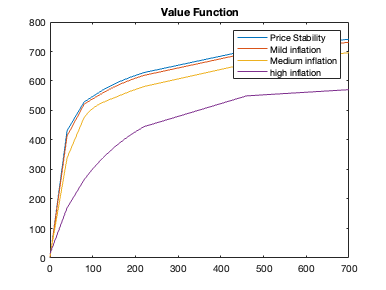

Distribution_all = 1000×4
  101.0588  120.7236   73.3769   99.6483
  118.9074   85.1662  140.4693  115.2493
  107.4570   80.9204   99.6635  128.4395
  106.7735  155.4749  110.4435   87.8063
   87.3363   78.6610   94.3109   96.3656
  132.3042  113.2953  121.3155  110.6391
  100.9237  121.6356   98.0816   98.4369
  120.8311  120.7805  117.3004  133.6075
  101.2125   79.7321   95.9596   82.8335
  105.1586  100.3894  118.6489  118.7175


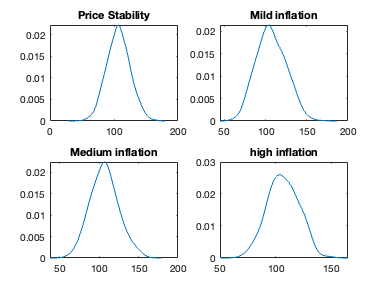

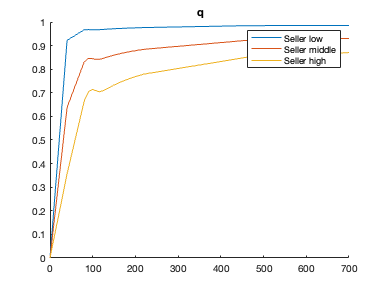

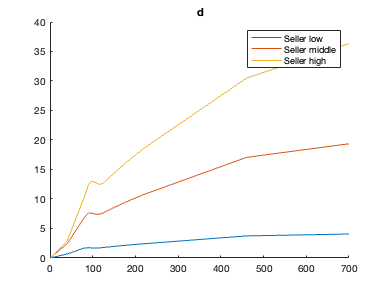

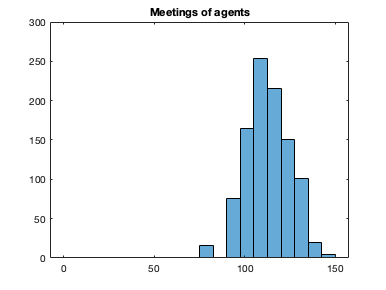

index = 1×10
     1     2     3     4     5     6     7     8     9    10


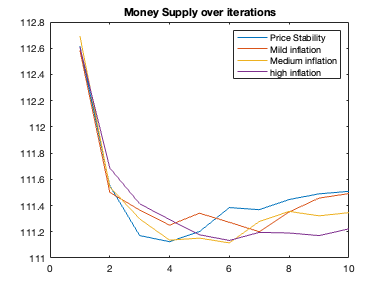

if display_plot_all==1

%Plot V
if display_plot_V==1
figure(1)
plot(m,V_all)
title('Value Function')
legend(mu_labels)

 end


%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
Distribution_all(Distribution_all==0)=0.001
    figure(2)
    hold on
for l=1:n_calibration
[f(:,l),xi(:,l)] = ksdensity(Distribution_all(:,l),'Support','positive','BoundaryCorrection'...
    ,'reflection','Bandwidth',std(Distribution_all(:,l))*smoothing_parameter); 
    subplot(2,2,l)
plot(xi(:,l),f(:,l))
title(mu_labels(1,l))
 end
end

hold off

%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution_all,grids*2)
 title('Distribution of Money holdings')
 legend(mu_labels)
 end




%Plot q (first iteration)
 if display_plot_q==1
figure(4)
hold on
plot(m,q_all(:,1,1))
plot(m,q_all(:,round(grids/2),1))
plot(m,q_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')

 end




%Plot d (last iteration)
 if display_plot_d==1
figure(5)
hold on
plot(m,d_all(:,1,1))
plot(m,d_all(:,round(grids/2),1))
plot(m,d_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end

%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end



% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
legend(mu_labels)
end

end

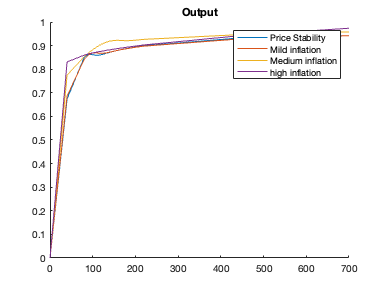


% Plot all q

 if display_plot_q_all==1
figure(10)
hold on
plot(m,q_all(:,3,1))
plot(m,q_all(:,3,2))
plot(m,q_all(:,3,3))
plot(m,q_all(:,3,4))
legend(mu_labels)
hold off
title('Output')
 end

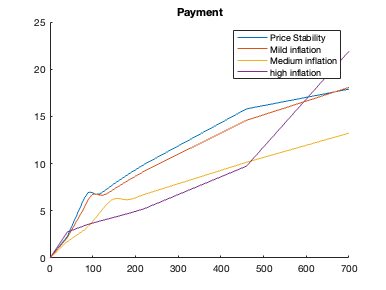


% Plot all d


  if display_plot_d_all==1
figure(11)
hold on
plot(m,d_all(:,3,1))
plot(m,d_all(:,3,2))
plot(m,d_all(:,3,3))
plot(m,d_all(:,3,4))
legend(mu_labels)
hold off
title('Payment')
 end






toc

Elapsed time is 119.967952 seconds.


## Tables

data_table=[average_q;average_price;std_distribution;velocity; average_real_balances]'

data_table = 4×5
    0.8588    8.1591   17.9780    0.0628   13.6667
    0.8587    8.5526   17.8763    0.0659   13.0359
    0.8417    7.3901   17.8132    0.0559   15.0670
    0.8600    4.8780   14.0622    0.0377   22.8007


figure(20)
 t=uitable(figure,'Data', data_table, 'Position', [100 100 500 200])

t =   Table with properties:

                Data: [4×5 double]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [100 100 500 200]
               Units: 'pixels'

  Show all properties


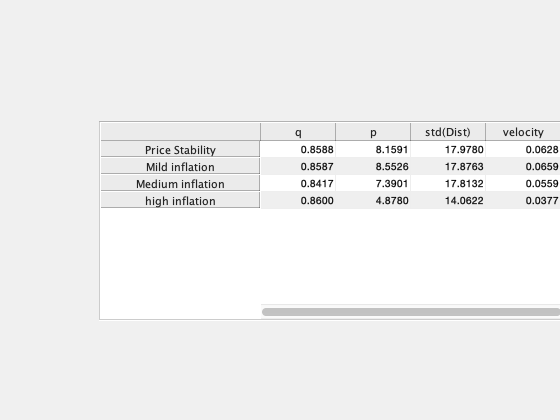

set(t, 'columnname', {'q', 'p','std(Dist)','velocity', 'real balances'})
set(t, 'rowname', mu_labels)